## Q2

Data for each frequencies are saved in freq_data_{d}.mat file, where d is integer value representing index of frequency in array given below.

clear all;
freq_array = [0.5 1.0 2.0 2.5 3.0 3.5 ...
        4.0 4.5 5.0 8.0 12.00 16.0 20.0 30.0];

Us = zeros(length(freq_array),1);
Phis = zeros(length(freq_array),1);
M = zeros(length(freq_array),1);

disp ("Running data cleaning")

Running data cleaning


for i = 1:length(freq_array)
    fileName = sprintf("freq_data_%d.mat",i);
    disp("Reading file ...")
    load(fileName)
    figure()
    
    % -- Seperating time, input and output values
    f = freq_array(i);

    t = data(1,:)';
    u = data(2,:)';
    v = data(4,:)';

    % -- Masking and removing first 5 second of transient data

    t_mask = t >= 5;

    t = t(t_mask);
    u = u(t_mask);
    v = v(t_mask);

    med_filter_v = medfilt1(v,4);
    v = med_filter_v;
    
    fprintf("Interpolating data for %d",f)
    data = interpolateSineData(t,v,f);
    
    % -- Storing data for different frequencies 
    fprintf("Storing data for %d",f)
    Us(i) = data.U;
    Phis(i) = data.Phi;
    M(i) = data.M;
end

Reading file ...


Interpolating data for 5.000000e-01

Storing data for 5.000000e-01

Reading file ...


Interpolating data for 1

Storing data for 1

Reading file ...


Interpolating data for 2

Storing data for 2

Reading file ...


Interpolating data for 2.500000e+00

Storing data for 2.500000e+00

Reading file ...


Interpolating data for 3

Storing data for 3

Reading file ...


Interpolating data for 3.500000e+00

Storing data for 3.500000e+00

Reading file ...


Interpolating data for 4

Storing data for 4

Reading file ...


Interpolating data for 4.500000e+00

Storing data for 4.500000e+00

Reading file ...


Interpolating data for 5

Storing data for 5

Reading file ...


Interpolating data for 8

Storing data for 8

Reading file ...


Interpolating data for 12

Storing data for 12

Reading file ...


Interpolating data for 16

Storing data for 16

Reading file ...


Interpolating data for 20

Storing data for 20

Reading file ...


Interpolating data for 30

Storing data for 30

disp("Finished cleaning");

Finished cleaning


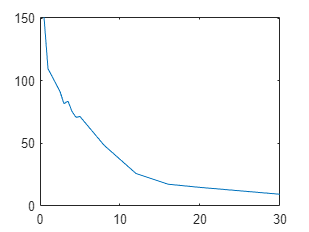

plot(freq_array,Us)

## Testing plot for predicted and the measured value

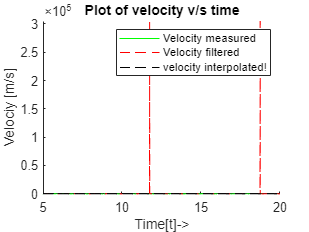

test_index = 2;
fileName = sprintf("freq_data_%d.mat",test_index);

f = freq_array(test_index);
%-- Input datas 
load(fileName);
% -- loading data from the system
t = data(1,:)';
u = data(2,:)';
v = data(4,:)';

t_mask = t >= 5;

t = t(t_mask);
u = u(t_mask);
v = v(t_mask);

%-- Filtered velocity
med_filter_v =  medfilt1(v,4);
% -- Interpolated parameters
U_i = Us(test_index); Phi_i = Phis(test_index);
M_i = M(test_index);
w = 2*pi*f;
interpolatedSine = U_i*sin(w*t + Phi_i) + M_i;

figure();
hold on;
plot(t,med_filter_v,'g')
plot(t,v,'r--');
plot(t,interpolatedSine,'k--')
xlabel("Time[t]->")
ylabel("Velociy [m/s]")
title("Plot of velocity v/s time")
legend("Velocity measured","Velocity filtered","velocity interpolated!")
hold off;

## Plotting systems measured response and it's gain and phase response according to bode plot

m = 6.7145e-04;
b = 0.0077;
dc_p = 0.2681;
dc_m = -0.2675;
K = 1/b;
tau = m/b;

% Update m and b to update value

figure ();
hold on;

title("Plot of magnitude v/s frequency...");
xlabel("w [rad/s]->");
ylabel("Amplitude |Y(w)|")
%w = logspace(-3,3,3000);
w = linspace(0,200,4000);

m_up = 7.0851e-04;
b_up = 0.0090;

K_up = 1/b_up;
tau_up = m_up/b_up;

G_j = @(w) []

G_j = function_handle with value:
    @(w)[]


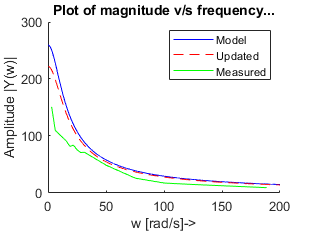

G_jw_up = 2*K_up./sqrt((tau_up*w).^2 + 1);

G_jw = 2*K./sqrt((tau*w).^2+1);
plot(w,G_jw,'b')
plot(w,G_jw_up,'r--')

Us_decibel = Us;
w_arr = 2*pi*freq_array;
plot(w_arr,Us_decibel,'g');

legend("Model","Updated","Measured")


figure();
hold on;
phi = atan2(-tau*w,1);
plot(w,rad2deg(phi),'b');
phi_updated = atan2(-tau_up*w,1)

phi_updated =          0   -0.0039   -0.0079   -0.0118   -0.0157   -0.0197   -0.0236   -0.0276   -0.0315   -0.0354   -0.0394   -0.0433   -0.0472   -0.0511   -0.0551   -0.0590   -0.0629   -0.0668   -0.0708   -0.0747   -0.0786   -0.0825   -0.0864   -0.0903   -0.0942   -0.0981   -0.1020   -0.1059   -0.1098   -0.1137   -0.1176   -0.1215   -0.1253   -0.1292   -0.1331   -0.1369   -0.1408   -0.1447   -0.1485   -0.1524   -0.1562   -0.1600   -0.1639   -0.1677   -0.1715   -0.1754   -0.1792   -0.1830   -0.1868   -0.1906


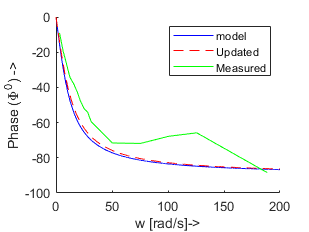

plot(w,rad2deg(phi_updated),'r--')
plot(w_arr,rad2deg(Phis),'g');

xlabel("w [rad/s]->");
ylabel("Phase (\Phi^0) ->")
legend("model","Updated","Measured");